# **Progetto regolatore con luogo delle radici (strada scorretta -> vedi find_R)**

#### inizializzazione dell'ambiente

clear
close all
clc

#### Definizione della funzione di trasferimento del processo

% parameters
Tau = 0.07;
T = 0.12;
mu = 1;

% G_ = G not delayed
G_ = tf(mu, [T 1 0]);

% G
G = G_;
G.IODelay = Tau

G =
 
                      1
  exp(-0.07*s) * ------------
                 0.12 s^2 + s
 
Continuous-time transfer function.



**Approssimo con Padé il ritardo, per trovare G approssimata**

%pade approximation
order = 2;
[numrit, denrit] = pade(Tau, order);
G_rit = tf(numrit, denrit)

G_rit =
 
  s^2 - 85.71 s + 2449
  --------------------
  s^2 + 85.71 s + 2449
 
Continuous-time transfer function.




%G approximated
G_approx = G_ * G_rit

G_approx =
 
            s^2 - 85.71 s + 2449
  -----------------------------------------
  0.12 s^4 + 11.29 s^3 + 379.6 s^2 + 2449 s
 
Continuous-time transfer function.



**Confronto G e G approx, risposta indiciale**

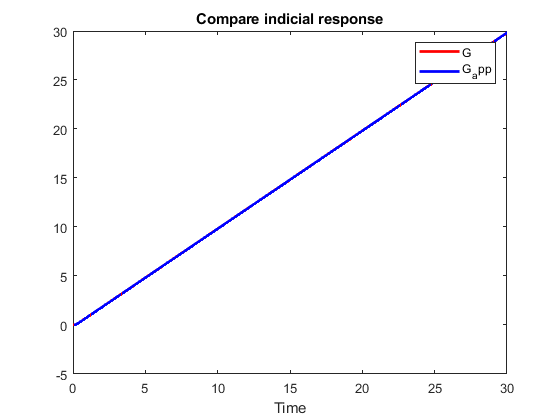

%COMPARE INDICAL RESPONSE
tfinal = 30;

[risp_indiciale_G, tempo_G] = step(G, tfinal);
[risp_indiciale_Gapp, tempo_Gapp] = step(G_approx, tfinal);

% Plot the first graph
plot(tempo_G, risp_indiciale_G, 'r-', 'LineWidth', 2); % Red line

hold on;

% Plot the second graph
plot(tempo_Gapp, risp_indiciale_Gapp, 'b-', 'LineWidth', 2); % Blue line

% Add labels and a legend
xlabel('Time');
ylabel('');
title('Compare indicial response');
legend('G', 'G_app');

% Turn off the hold to allow for new plots
hold off;

%RESULTS: indicial response is the same

**Confronto G e G approx, risposta in frequenza**

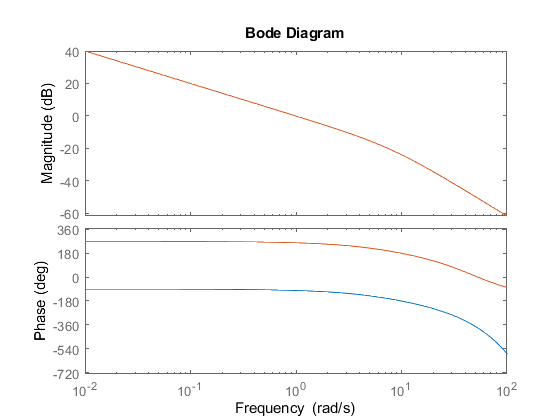

%COMPARE BODE DIAGRAM
wmin = 0.01;
wmax= 100;

%blue for G, red for G_approx
bode (G, G_approx,  {wmin,wmax});


%NOTE: phase difference = 360° -> no phase difference


%here are reported computed value in w = 1, 10, 20, 30, 40, 50, 100
w_test = [1 10 20 30 40 50 100];

[mod_check, ph_check] = bode(G,w_test);
[mod_check_a, ph_check_a] = bode(G_approx,w_test);


phase_diff = ph_check - ph_check_a

phase_diff = phase_diff(:,:,1) =

 -360.0000


phase_diff(:,:,2) =

 -360.0130


phase_diff(:,:,3) =

 -360.3788


phase_diff(:,:,4) =

 -362.4491


phase_diff(:,:,5) =

 -368.2437


phase_diff(:,:,6) =

 -379.1711


phase_diff(:,:,7) =

 -498.3134



%RESULTS:
% - magnitude is the same
% - phase difference is around 0 in dipendence of the order of pade approximation
%   (1ord: w<=10, 2ord: w<=30)

**Inizio il progetto del regolatore con luogo delle radici. Uso G approssimato.**

**Trovo poli e zeri di G_approx**

[poli, zeri] = pzmap(G_approx)

poli =    0.0000 + 0.0000i
 -42.8571 +24.7436i
 -42.8571 -24.7436i
  -8.3333 + 0.0000i


zeri =   42.8571 +24.7436i
  42.8571 -24.7436i


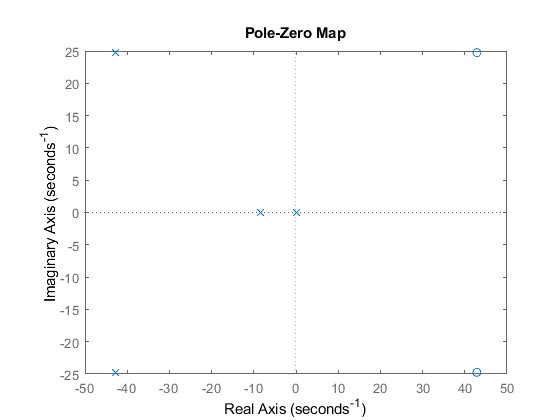

pzmap(G_approx)

**Opero su luogo delle radici e trovo regolatore**

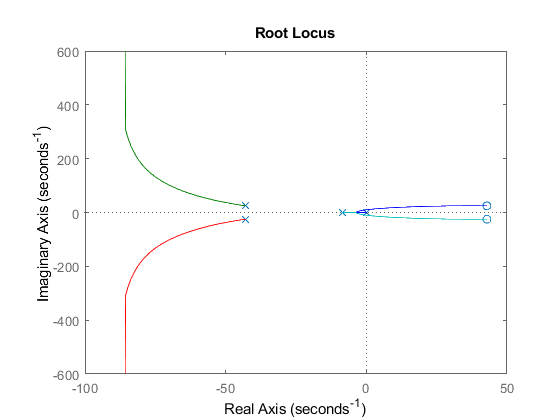

%traccio
rlocus(G_approx)

%study G
%rltool(G_approx);

%results: a possibile solution is adding two zeros and two poles:
% - zero1 in -8.3333
% - zero2 in -41
% - two pole in -200 (high frequency poles for fisical feasibility)


**Trovo fdt del regolatore, senza guadagno**

%defining subpiecies of R

Z1 = tf([0.12 1], 1);
Z2 = tf([0.0244 1], 1);
P1 = tf([0.005 1], 1);
P12 = P1*P1;             %two poles

%computing R (it misses gain)
R_no_gain = Z1*Z2/P12

R_no_gain =
 
  0.002928 s^2 + 0.1444 s + 1
  ---------------------------
   2.5e-05 s^2 + 0.01 s + 1
 
Continuous-time transfer function.



**Controllo se ho messo bene i poli e gli zeri. Individuo la posizione desiderata dei poli ad anello chiuso per trovare il guadagno del regolatore**

%L_no_gain = G_approx*R_no_gain
%rltool(L_no_gain)

**Trovo un guadagno per il regolre mu_R che soddisfi i requisiti Ta < 0.2s e S%<5%**

%NEEDING: real pole at -20 (studied from rltool)
%track relationship poles-reg.gain
L_no_gain = G_approx* R_no_gain; %function open loop to study
[r,k] = rlocus(L_no_gain);

%our pole of interest is the last of this column.
display(r(:,30))        %index 30 is the nearest to the desired situation

   1.0e+02 *

  -0.0833 + 0.0000i
  -2.1302 + 1.1000i
  -2.1302 - 1.1000i
  -0.2001 + 0.1666i
  -0.2001 - 0.1666i
  -0.1966 + 0.0000i



display(k(30))

    7.8172



%mu_R = k(30);
mu_R = 7.9;

**Risultati: regolatore e funzione open loop **

R = minreal(mu_R * R_no_gain)

R =
 
  925.2 s^2 + 4.563e04 s + 316000
  -------------------------------
        s^2 + 400 s + 4e04
 
Continuous-time transfer function.



L = G * R %do not use approximated G

L =
 
                    925.2 s^2 + 4.563e04 s + 316000
  exp(-0.07*s) * -------------------------------------
                 0.12 s^4 + 49 s^3 + 5200 s^2 + 4e04 s
 
Continuous-time transfer function.



**Faccio delle prove su L in anello chiuso**

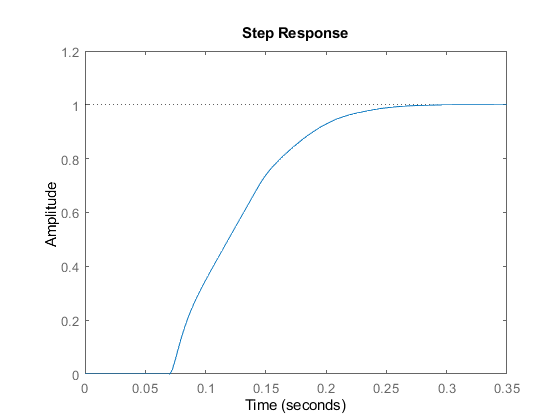

%close loop
L_c = feedback(L, 1);

%[poliLc, zeriLc] = pzmap(L_c)
%pzmap(L_c)


%indicial response
step(L_c)

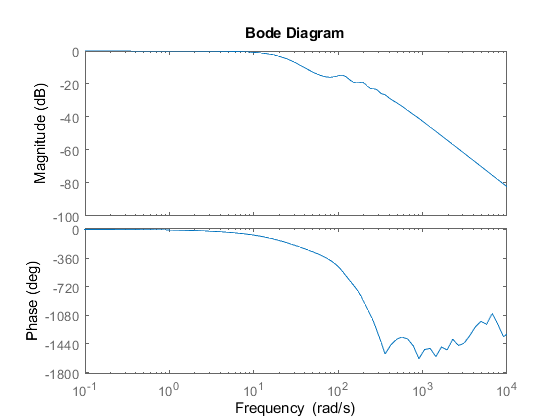

%bode diagram
bode(L_c)


%RESULTS:

% R = 925.2 s^2 + 4.563*10^4 s + 316000
%     ---------------------------------
%       s^2 + 400 s + 4000

%Prestational characteristics close loop:
%  astatismo gradino
%  Ta(2%) < 0.25s (anche se avevamo richiesto 0.2s)
%  no sovraelongazione
%  low pass filter, wsup about 10rad/s

**Discretizzo G**

%discretizzazione con Tc
Tc = 0.25;
G_d = c2d(G, Tc)

G_d =
 
           0.08678 z^2 + 0.129 z + 0.003118
  z^(-1) * --------------------------------
                z^2 - 1.125 z + 0.1245
 
Sample time: 0.25 seconds
Discrete-time transfer function.



**Discretizzo R e ne controllo la stabilità **

%discretizzazione con Tc
%Tc = 0.25;
R_d = c2d(R, Tc)

R_d =
 
  925.2 z^2 - 917.3 z + 6.976e-18
  -------------------------------
   z^2 - 3.857e-22 z + 3.72e-44
 
Sample time: 0.25 seconds
Discrete-time transfer function.



% stability check (poles has to be internal to unitary loop
[poliR_d, zeriR_d] = pzmap(R_d)

poliR_d = 	1.0e+-21 *

   0.1929 + 0.0000i
   0.1929 - 0.0000i


zeriR_d =     0.9915
    0.0000


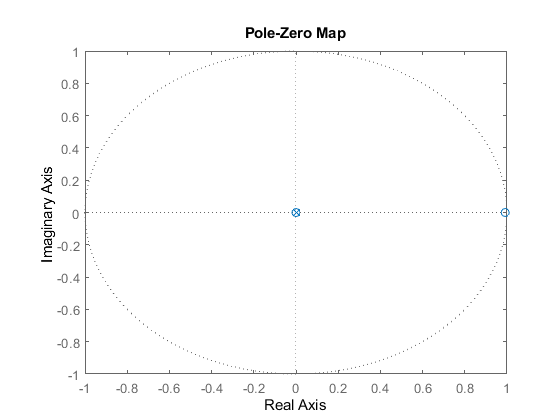

pzmap(R_d)

%R_d -> stability

% simplify deleting coefficients near 0
R_d = tf([925.2 -197.3 0], [1 0 0], 0.25)

R_d =
 
  925.2 z^2 - 197.3 z
  -------------------
          z^2
 
Sample time: 0.25 seconds
Discrete-time transfer function.



% simplify the pole in 0 (possible since it's internal to unitary loop)
R_d = minreal(R_d)

R_d =
 
  925.2 z - 197.3
  ---------------
         z
 
Sample time: 0.25 seconds
Discrete-time transfer function.



% stability check (poles has to be internal to unitary loop
[poliR_d, zeriR_d] = pzmap(R_d)

poliR_d = 0

zeriR_d = 0.2133

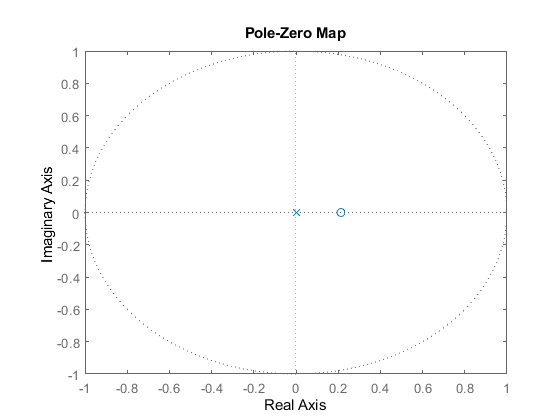

pzmap(R_d)

**Define loop functions**

%open loop
L_d = R_d * G_d

L_d =
 
                                                                
           80.29 z^4 + 39.73 z^3 - 115.4 z^2 - 2.86 z           
                                                                
                                                     + 2.175e-20
                                                                
  z^(-1) * -----------------------------------------------------
                                                                
           z^4 - 1.125 z^3 + 0.1245 z^2 - 4.803e-23 z           
                                                                
                                                     + 4.632e-45
                                                                
 
Sample time: 0.25 seconds
Discrete-time transfer function.




%close loop
L_d_c = feedback(L_d, 1)

L_d_c =
 
     80.29 z^4 + 39.73 z^3 - 115.4 z^2 - 2.86 z + 2.175e-20
  ------------------------------------------------------------
  z^5 + 79.16 z^4 + 39.86 z^3 - 115.4 z^2 - 2.86 z + 2.175e-20
 
Sample time: 0.25 seconds
Discrete-time transfer function.



**Some tests**

%TEST on L_d_c

%poles and zeros position
[poliL_d_c, zeriL_d_c] = pzmap(L_d_c)

poliL_d_c =   -78.6390
   -1.4924
    0.9915
   -0.0246
    0.0000


zeriL_d_c =    -1.4618
    0.9915
   -0.0246
    0.0000


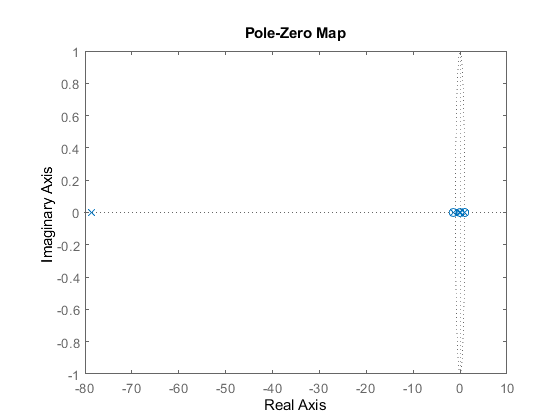

pzmap(L_d_c)

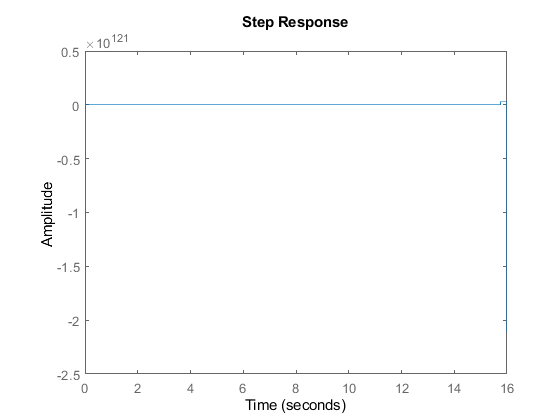



%indicial response
step(L_d_c)

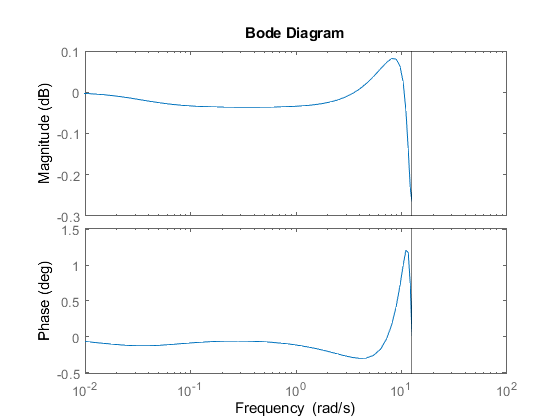


%bode diagram
%bode(L_d_c)



%RESULTS: unfurtunately this approch didn't give the correct fdt